# Team doubleE - Task 1 Report

**Team Members: Andrew Wunderlich, Jay Desai, Miles Leonard-Albert **

***CSCE585 - Machine Learning Systems***

***Fall 2020 Adversarial ML Project***

This report provides insight and analysis into Task 1, in which we create adversarial examples using the Athena framework.

clear variables %reset workspace

## Set Project Directory

% which('Task1Report.mlx')
% cd .. %set working directory to up one level from current directory
% projectdir = pwd
projectdir = 'C:\Users\andre\CSCE585_local\project-athena'

projectdir = 'C:\Users\andre\CSCE585_local\project-athena'

## Plot a few examples of each attack

This task includes 15 attacks, featuring 3 attack types, each at 5 different intensities.  Below we plot a few examples of images from the MNIST dataset modified using the following attacks:

Spatial transformation, w/ max roation:

- 10 degrees

- 20 degrees

- 30 degrees

- 40 degrees

- 50 degrees

PGD, with epsilon:

- 0.03

- 0.07

- 0.10

- 0.20

- 0.30

JSMA, with theta:

- 0.03

- 0.07

- 0.10

- 0.20

- 0.30

attacks = categorical({'SpaXfm 10' 'SpaXfm 20' 'SpaXfm 30' 'SpaXfm 40' 'SpaXfm 50'...
            'PGD 0.03' 'PGD 0.07' 'PGD 0.10' 'PGD 0.20' 'PGD 0.30'...
            'JSMA 0.03' 'JSMA 0.07' 'JSMA 0.10' 'JSMA 0.20' 'JSMA 0.30'});

## Analyze Error Rate by Attack for Each Defense

This work uses the following defense models:

- UM: The undefended model (a single CNN with no special defenses)

- MV: "Vanilla Athena" with the Majority Voting ensemble strategy

- AVEP: "Vanilla Athena" with the Average Probability ensemble strategy

- PGD-ADT: PGD Adversarial Training, a state-of-the-art Adversarial Defense

For each defense, we ran all 15,000 perturbed images (15 attacks * 1,000 of the 10,000 test images in MNIST) and obtained predictions for each.  We stored the 1,000 correct values alongside the 15,000 predicted values for each adversarial example in a single datatable, from which we can calculate error rates and plot relevant variables.

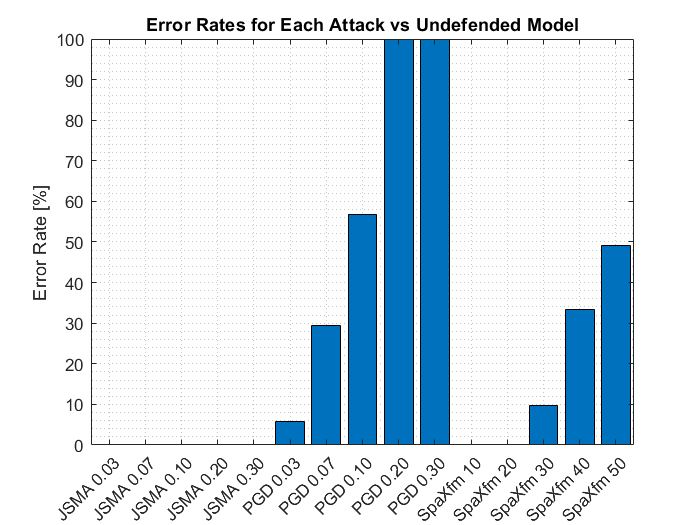

load([projectdir,'/saved_attacks/dataTable.mat'])

labels = dataTable(:,1); %correct labels are in first column
predictions = dataTable(:,2:end); %predicted labels for AEs are in the other columns
num_images = length(labels); 
num_attacks = size(predictions,2);

errortable = -ones(size(predictions));
all_err_rates = -ones(1, num_attacks);

for i = 1:num_attacks
    errortable(:,i) = (predictions(:,i) ~= labels);
    all_err_rates(i) = mean(errortable(:,i));
end

bar(attacks, all_err_rates*100); ylabel('Error Rate [%]');  

title('Error Rates for Each Attack vs Undefended Model');